close all;
clear all;
clc;

load('gaze.mat');

Error using load
'gaze.mat' is not found in the current folder or on the MATLAB path, but exists in:
    D:\Github\Applied_Project\Matlab Template & Test\Template and Test\Test

Change the MATLAB current folder or add its folder to the MATLAB path.

load('events.mat');

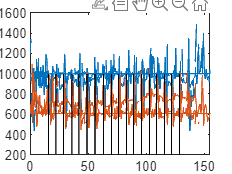

load('gaze1.mat');
load('event1.mat');

Xs_gaze = X_gaze/1000000;

% plot(Xs_gaze,GazeX);

GazeX = fillmissing(GazeX,"movmean",20);
GazeY = fillmissing(GazeY,"movmean",20);

GazeX = movmean(GazeX,30);
GazeY = movmean(GazeY,30);

plot(Xs_gaze,GazeX);
hold on;
plot(Xs_gaze,GazeY);
% plot(Xs_gaze,gazexy);
hold off;
% legend("X","Y");

Xs_idx = X_idx/1000000;

for i = 1:length(Xs_idx)
    line([Xs_idx(i) Xs_idx(i)], [200 1000], 'LineWidth', 0.5, 'Color', 'k');
end